# ShowGraph Demo

#### Read the model file

filename = "C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\orcvcr\orcvcr_model.json";
model = ThermoeconomicModel(filename,'Debug',false);

#### Show the available tables of the Result set

ListResultTables(model);


Tables Directory

 Table        Description                          Results                   Graph  
——————————————————————————————————————————————————————————————————————————————————————
 flows        Flows Definition Table               Productive Structure      off    
 processes    Processes Definition Table           Productive Structure      off    
 streams      Productive Groups Definition Table   Productive Structure      off    
 eflows       Flows Exergy Table                   Exergy Analysis           off    
 eprocesses   Processes Exergy Table               Exergy Analysis           off    
 estreams     Productive Groups Exergy Table       Exergy Analysis           off    
 tfp          FP Table                             Exergy Analysis           on     
 dfcost       Flows Exergy Cost                    Thermoeconomic Analysis   off    
 dcost        Process Exergy Cost                  Thermoeconomic Analysis   off    
 ducost       Process Unit Exergy Cost      

#### Show the default graph of a Result set

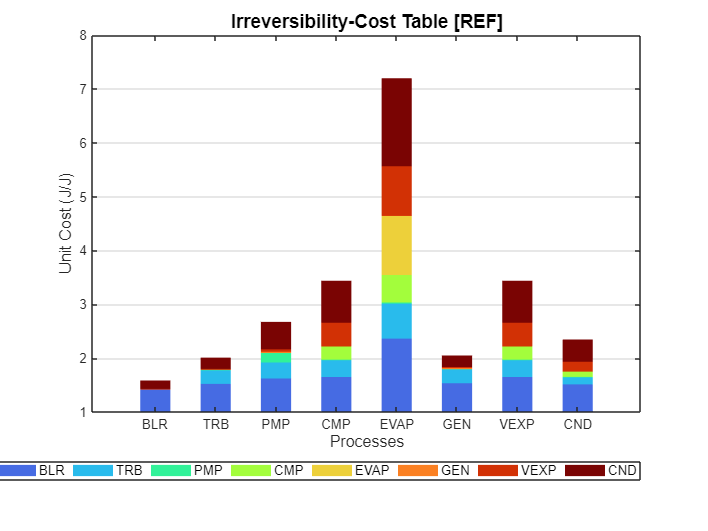

ShowGraph(model);

#### Show a specific table of the Result set

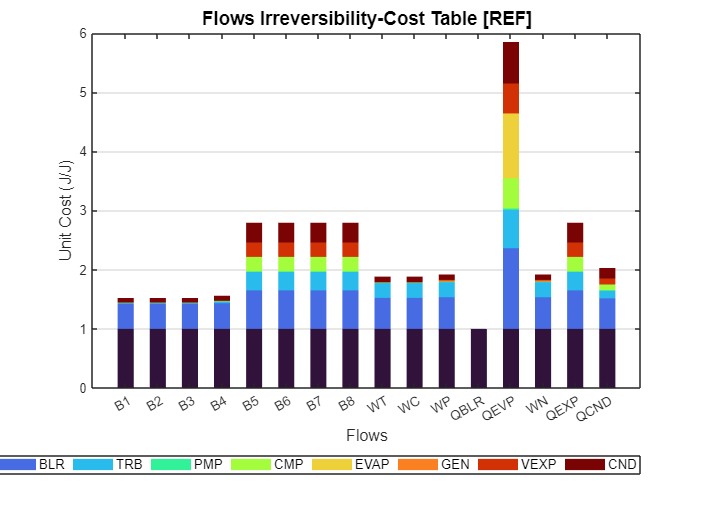

ShowGraph(model,'Graph','dfict');

#### Add Options depending of the Result set

**Thermoeconomic Diagnosis**

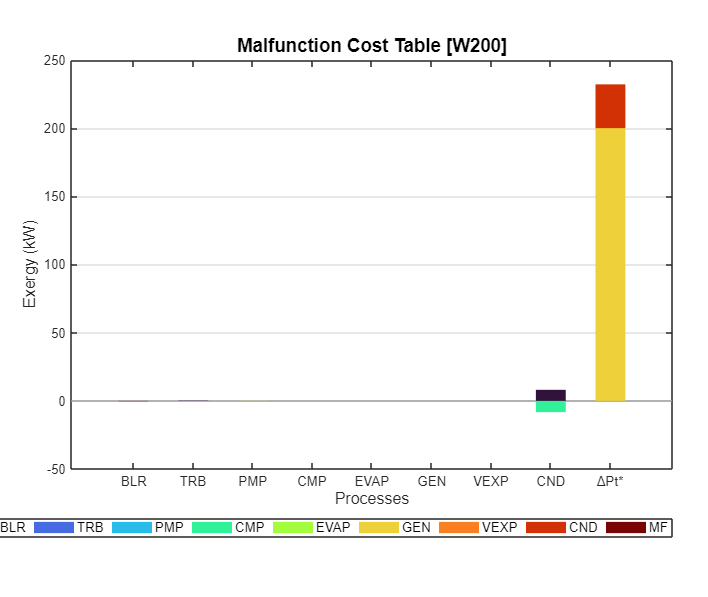

model.setDiagnosisMethod('WASTE_INTERNAL');
model.setState('W200');
res = model.thermoeconomicDiagnosis;
ShowGraph(res,'Graph','mfc');

Use` 'ShowOutput' `option for thermoeconomic diagnosis graphs

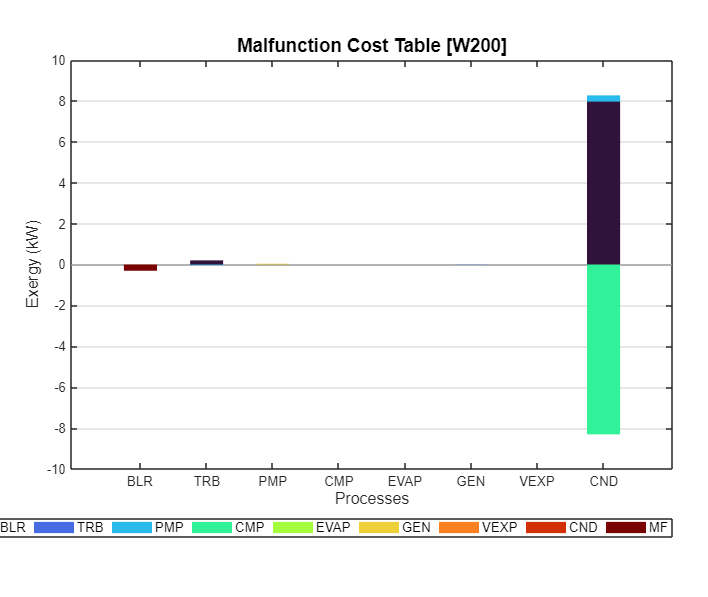

ShowGraph(res,'Graph','mfc','ShowOutput',false);

res.summaryDiagnosis;

Fuel Impact:        410.000 (kW)
Malfunction Cost:     0.306 (kW)



**Summary Results**

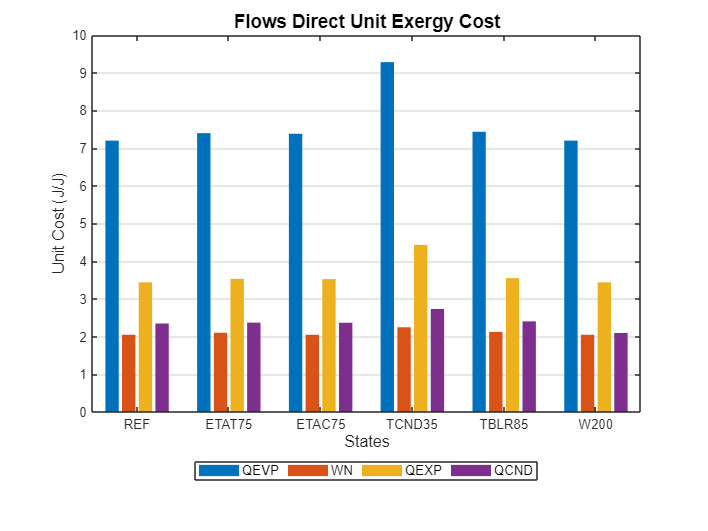

model.setSummary(true);
res=model.summaryResults;
ShowGraph(res);

Use the option `'Variables' `in Summary Results to select flows. By default all the `output flows` are shown.

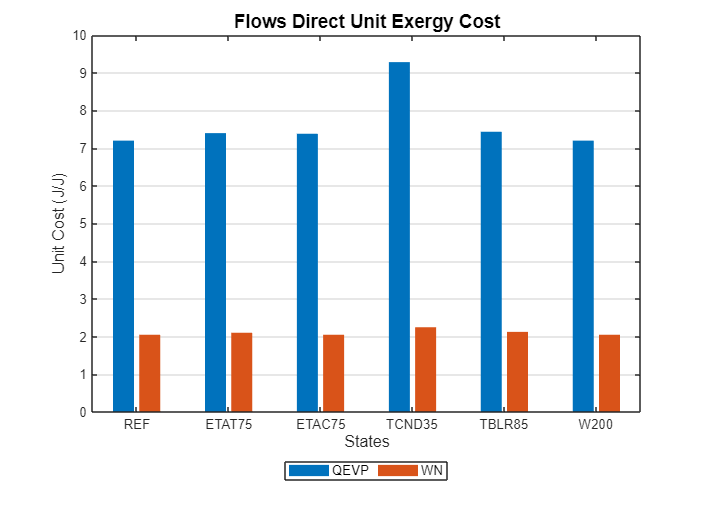

vars={'QEVP','WN'};
ShowGraph(res,'Graph','dfuc','Variables',vars);

**Waste Allocation**

Use the option `'WasteFlow' `to select the waste flow to show. By default `ActiveWaste` is used.

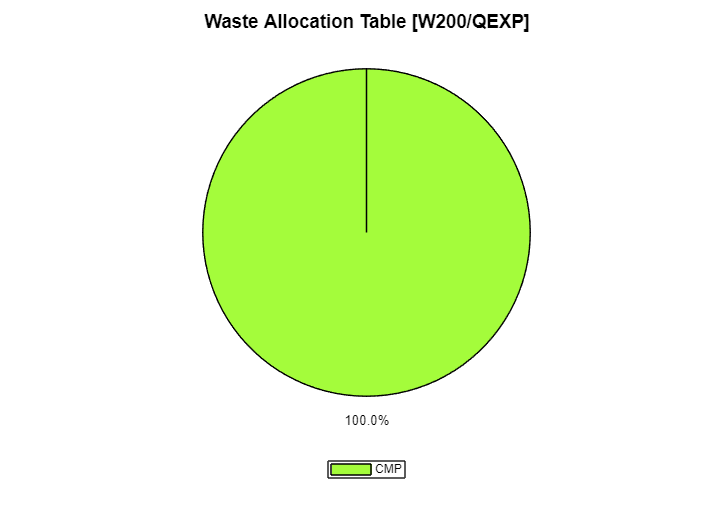

ShowGraph(model,'Graph','wa');

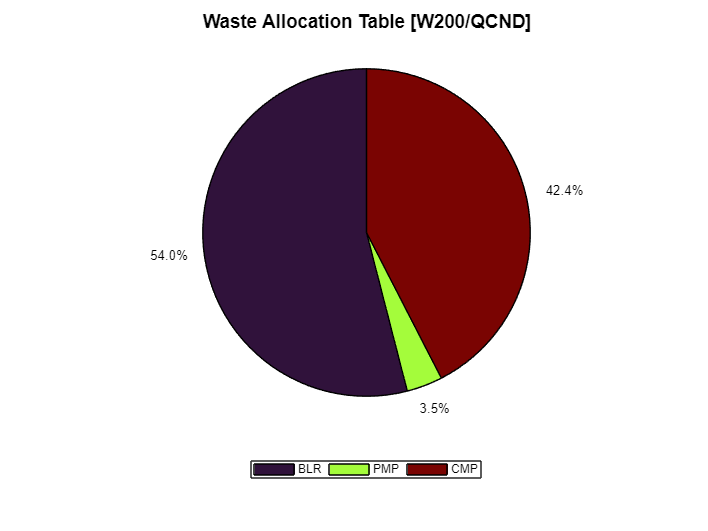

ShowGraph(model,'Graph','wa','WasteFlow','QCND');

**Diagram FP**

Use the option Colobar to show the colorbar. By default colobar is activated

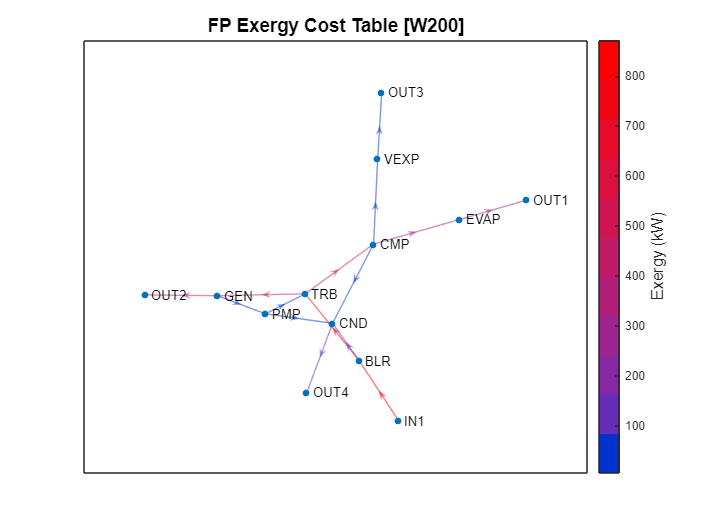

ShowGraph(model,'Graph','dcfp');

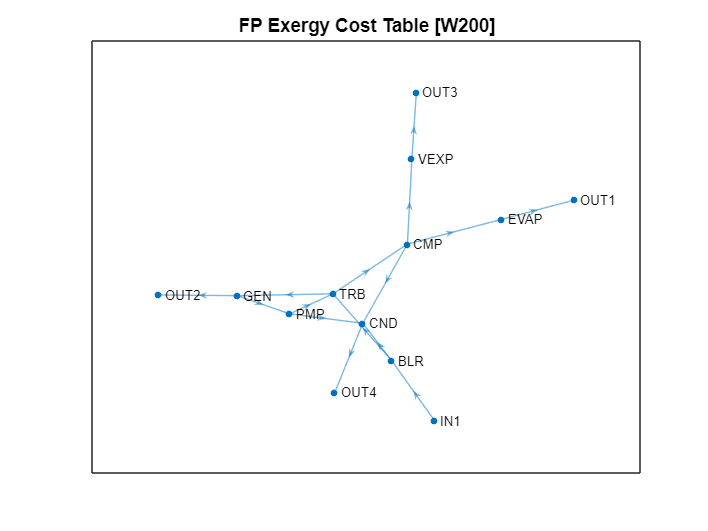

ShowGraph(model,'Graph','dcfp','Colorbar',false);

#### Additional Help

help ShowGraph

 ShowGraph - Shows a result table as a graph.
 	Depending on the graph, additional options could be used.
 
  Syntax 
   	ShowGraph(arg,Name,Value)
  
  Input Argument
  	arg - cResultSet object
 
  Name-Value Arguments
    Graph: Name of the table
      char array
    ShowOutput: Use for diagnosis tables
      false | true (default)
    WasteFlow: Waste flow key for waste allocation and recycling
      char array 
    Variables: Use for summary results. 
 	  cell array
    Colorbar: Use Colorbar in Diagram FP
      false | true (default)
 
  Example
    Show Graph Demo
 
  See also cGraphResults, cResultSet

